# A fair comparison between models

- Set to the maximun possible the number of shared parameters

- Shared parameters must have same estimation range

- Not shared parameters must have biological sense at its range

- Same parameters must be estimated for both models

## Model 7

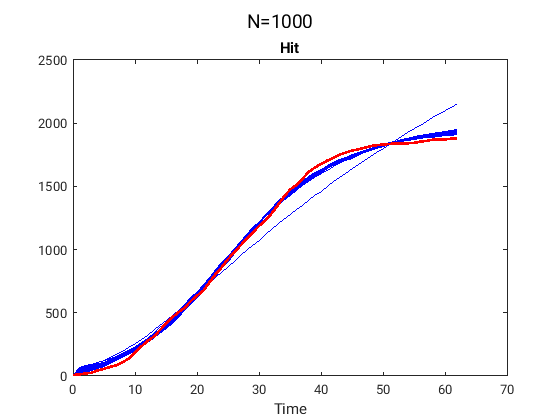

Sim13 Done
Sim26 Done
Sim39 Done
Sim52 Done
Sim51 Done
Sim50 Done
Sim49 Done
Sim48 Done
Sim47 Done
Sim46 Done
Sim45 Done
Sim44 Done
Sim43 Done
Sim42 Done
Sim41 Done
Sim40 Done
Sim12 Done
Sim11 Done
Sim10 Done
Sim9 Done
Sim8 Done
Sim7 Done
Sim6 Done
Sim5 Done
Sim4 Done
Sim3 Done
Sim2 Done
Sim1 Done
Sim171 Done
Sim170 Done
Sim169 Done
Sim168 Done
Sim167 Done
Sim166 Done
Sim165 Done
Sim164 Done
Sim163 Done
Sim162 Done
Sim161 Done
Sim160 Done
Sim159 Done
Sim158 Done
Sim157 Done
Sim156 Done
Sim155 Done
Sim154 Done
Sim153 Done
Sim152 Done
Sim151 Done
Sim150 Done
Sim149 Done
Sim148 Done
Sim147 Done
Sim146 Done
Sim25 Done
Sim24 Done
Sim23 Done
Sim22 Done
Sim21 Done
Sim20 Done
Sim19 Done
Sim18 Done
Sim17 Done
Sim16 Done
Sim15 Done
Sim14 Done
Sim290 Done
Sim289 Done
Sim288 Done
Sim287 Done
Sim286 Done
Sim285 Done
Sim284 Done
Sim283 Done
Sim282 Done
Sim281 Done
Sim280 Done
Sim279 Done
Sim278 Done
Sim277 Done
Sim276 Done
Sim275 Done
Sim274 Done
Sim273 Done
Sim272 Done
Sim271 Done
Sim270 Done
Sim26

load Results7.mat
clf
%T7.Properties.CustomProperties.output=1:7;
%T7.Estlsqc=T7.Estlsqc(:,1:70);
y7=gsua_eval(T7.Estlsqc,T7,xdata,ydata2);
ydata=ydata2;
for i=2:length(ydata)
ydata(i)=ydata2(i)-ydata2(i-1);
end

for i=2:size(y,2)
y(:,i)=y7(:,i)-y7(:,i-1);
end
y7=y;
clf
plot(xdata,[y7(1,:,1);ydata])

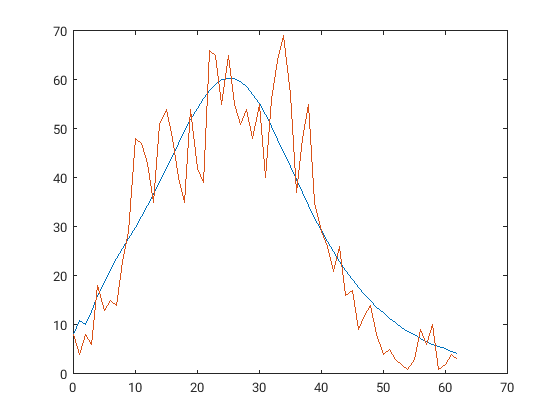

T7.Nominal=T7.Estlsqc(:,1);
th=sum(res<res(1)*1.01)
T7_2=gsua_ia(T7,T7.Estlsqc(:,1:th));

% M=gsua_dmatrix(T7,10000);
% T7.Properties.CustomProperties.output=1;
% [T7,J7,Y7]=gsua_sa(M,T7,'SensMethod','Distance');

load Results7_sa.mat
pltsa(T7,Y7,xdata,ydata)

th = 476

## Model 8

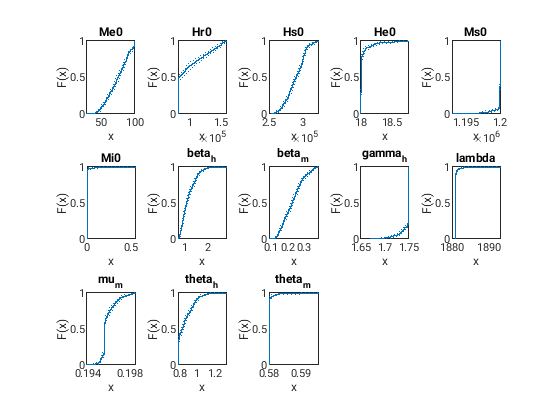

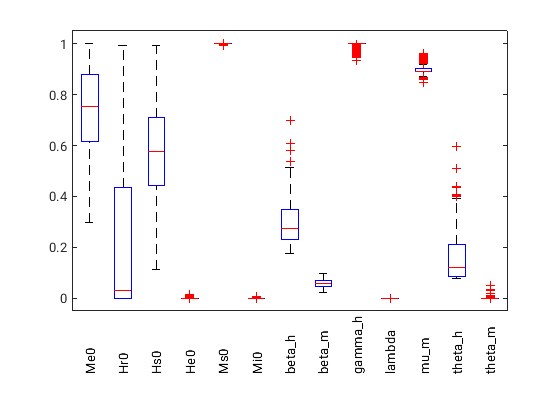

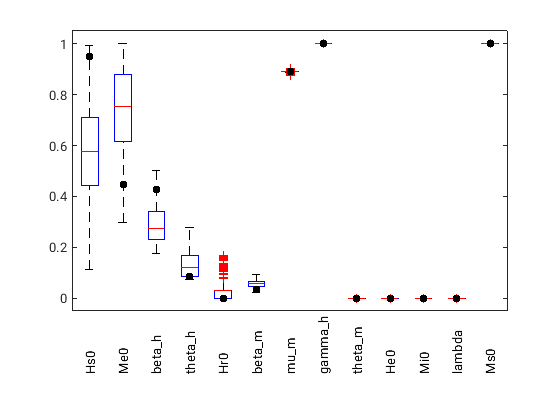

load Results8_complete.mat

clf
%T8.Properties.CustomProperties.output=1:8;
y8=gsua_eval(T8.Estlsqc,T8,xdata,ydata2);

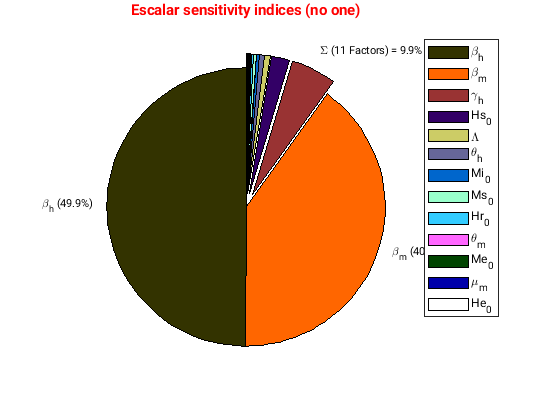

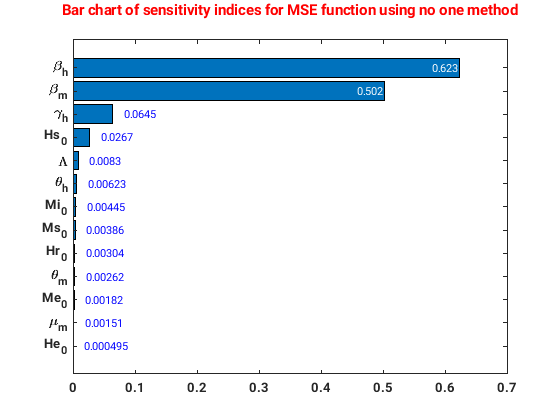

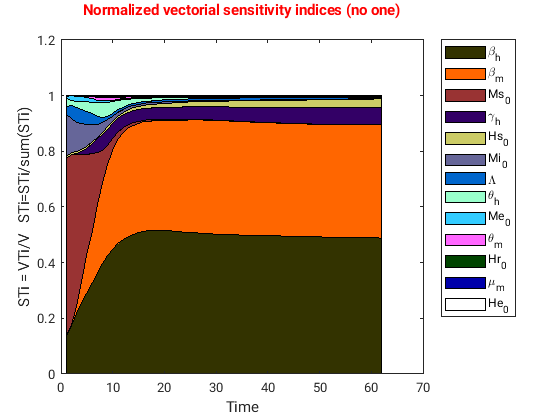

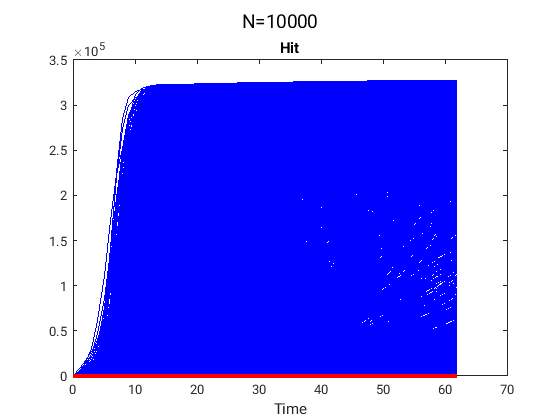

ydata=ydata2;
for i=2:length(ydata)

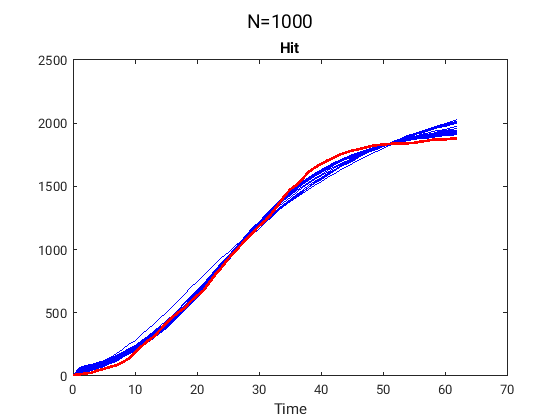

Sim13 Done
Sim26 Done
Sim39 Done
Sim52 Done
Sim12 Done
Sim25 Done
Sim38 Done
Sim51 Done
Sim11 Done
Sim24 Done
Sim37 Done
Sim50 Done
Sim10 Done
Sim23 Done
Sim36 Done
Sim9 Done
Sim49 Done
Sim22 Done
Sim8 Done
Sim35 Done
Sim48 Done
Sim21 Done
Sim7 Done
Sim34 Done
Sim47 Done
Sim20 Done
Sim33 Done
Sim6 Done
Sim19 Done
Sim46 Done
Sim5 Done
Sim32 Done
Sim4 Done
Sim18 Done
Sim45 Done
Sim31 Done
Sim3 Done
Sim17 Done
Sim44 Done
Sim30 Done
Sim2 Done
Sim16 Done
Sim43 Done
Sim29 Done
Sim15 Done
Sim1 Done
Sim28 Done
Sim42 Done
Sim171 Done
Sim14 Done
Sim27 Done
Sim41 Done
Sim170 Done
Sim40 Done
Sim169 Done
Sim290 Done
Sim409 Done
Sim168 Done
Sim289 Done
Sim528 Done
Sim408 Done
Sim167 Done
Sim527 Done
Sim288 Done
Sim407 Done
Sim166 Done
Sim526 Done
Sim287 Done
Sim406 Done
Sim165 Done
Sim525 Done
Sim164 Done
Sim405 Done
Sim286 Done
Sim524 Done
Sim163 Done
Sim404 Done
Sim523 Done
Sim162 Done
Sim285 Done
Sim403 Done
Sim161 Done
Sim522 Done
Sim284 Done
Sim402 Done
Sim160 Done
Sim521 Done
Sim283 Done
Sim40

ydata(i)=ydata2(i)-ydata2(i-1);
end
y=y8;
for i=2:size(y,2)
y(:,i)=y8(:,i)-y8(:,i-1);
end

clf
plot(xdata,[y(1,:,1);ydata])

T8.Nominal=T8.Estlsqc(:,1);
th=sum(res<res(1)*1.01)
T7_8=gsua_ia(T8,T8.Estlsqc(:,1:th));

%M=gsua_dmatrix(T8,10000);
%[T8,J8,Y8]=gsua_sa(M,T8,'SensMethod','Distance');
load('Results8_sa.mat')
pltsa(T8,Y8,xdata,ydata)

## Model10

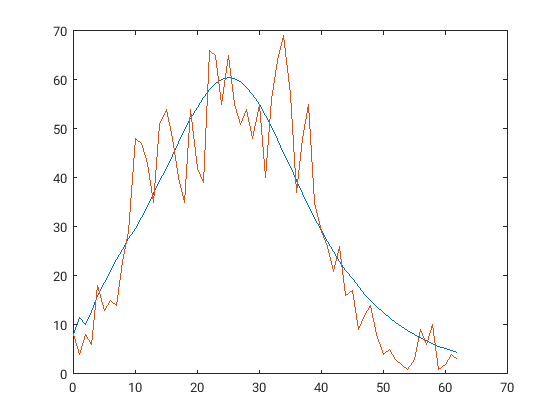

%M=gsua_dmatrix(T10,10000);
%[T10,J10,Y10]=gsua_sa(M,T10,'SensMethod','Distance');

load Results10_complete.mat
clf

th = 158

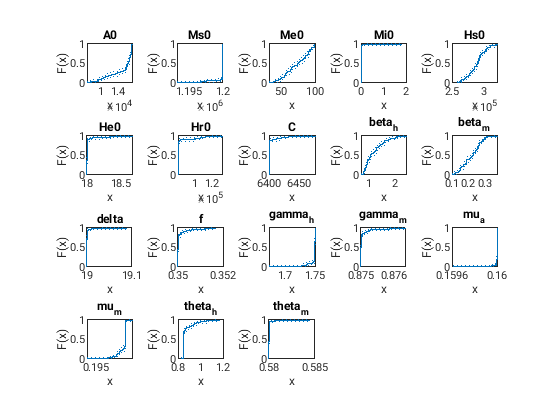

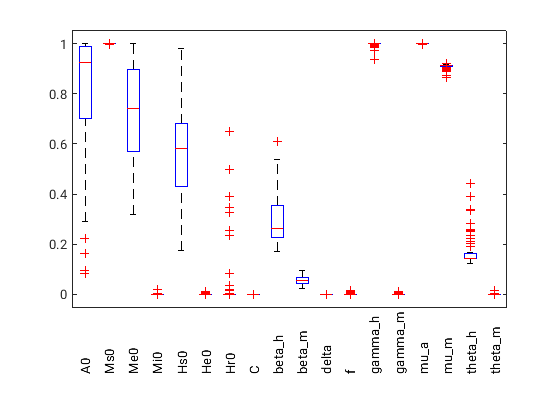

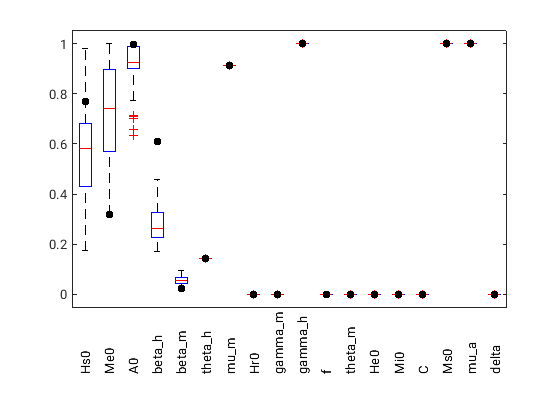

%T10.Properties.CustomProperties.output=1:10;

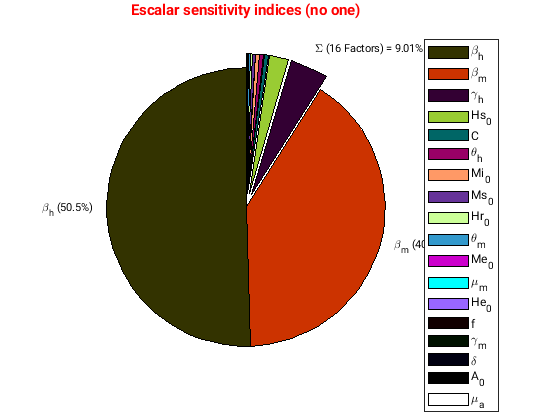

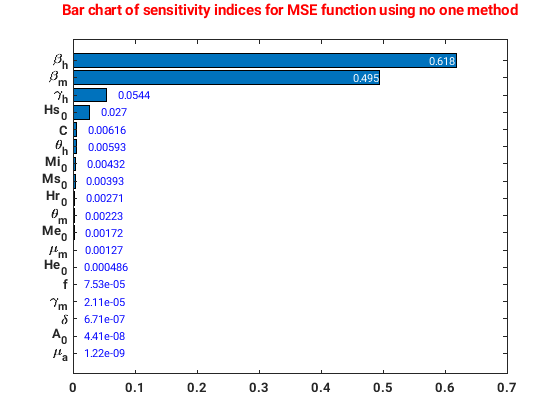

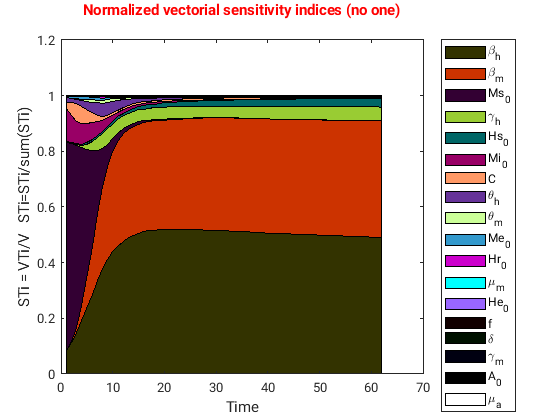

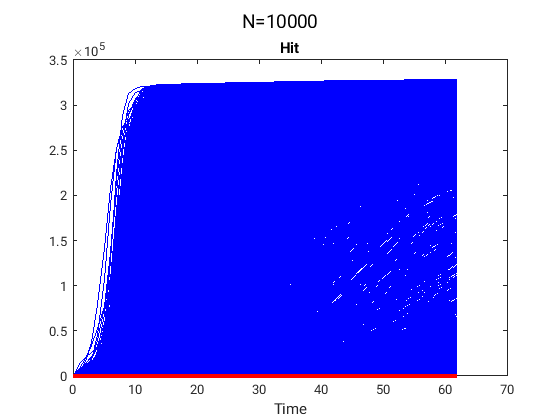

y10=gsua_eval(T10.Estlsqc,T10,xdata,ydata2);
ydata=ydata2;
for i=2:length(ydata)
ydata(i)=ydata2(i)-ydata2(i-1);
end

y=y10;
for i=2:size(y,2)
y(:,i)=y10(:,i)-y10(:,i-1);
end
clf
plot(xdata,[y(1,:,1);ydata])

T10.Nominal=T10.Estlsqc(:,1);
th=sum(res<res(1)*1.01)
T10_2=gsua_ia(T10,T10.Estlsqc(:,1:th));

Sim13 Done
Sim26 Done
Sim39 Done
Sim52 Done
Sim25 Done
Sim12 Done
Sim38 Done
Sim51 Done
Sim24 Done
Sim37 Done
Sim11 Done
Sim50 Done
Sim23 Done
Sim10 Done
Sim36 Done
Sim22 Done
Sim49 Done
Sim9 Done
Sim21 Done
Sim35 Done
Sim48 Done


load('Results10_sa.mat')
pltsa(T10,Y10,xdata,ydata)

## Ranges comparison

### 3 models

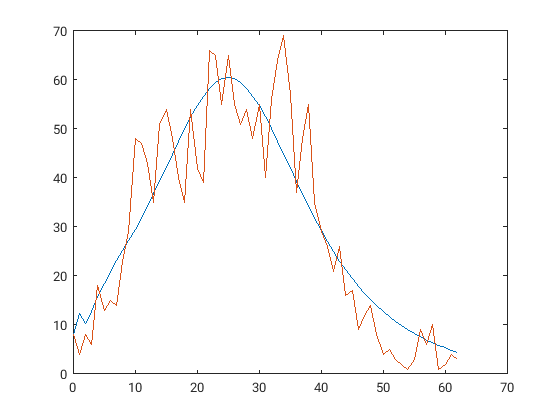

clf
load Rcomp.mat
major_set=intersect(T10.Properties.RowNames,intersect(T7.Properties.RowNames,T10.Properties.RowNames));
minor_set=intersect(T8.Properties.RowNames,T10.Properties.RowNames);
Tma1=T10(major_set,'Range');
Tma8=T8(major_set,'Range');

Tma7=T7(major_set,'Range');
D1 = floor(sqrt(size(Tma1,1))); % Number of rows of subplot
D2 = D1+ceil((size(Tma1,1)-D1^2)/D1);

th = 136

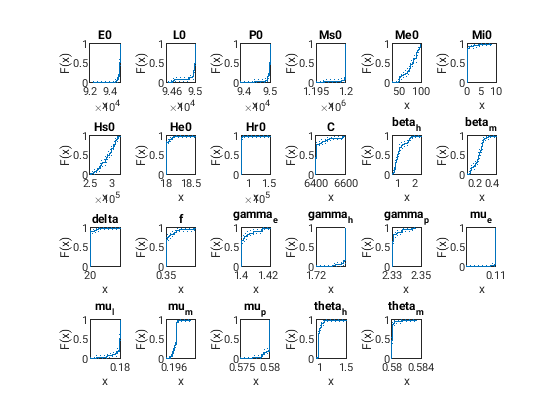

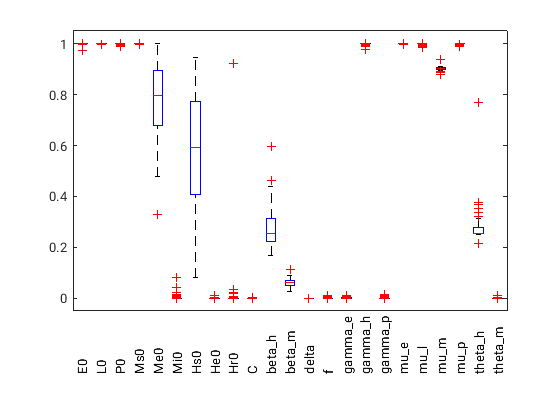

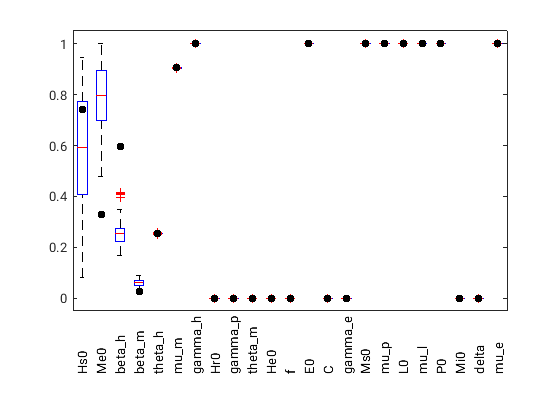

for i=1:size(Tma1,1)

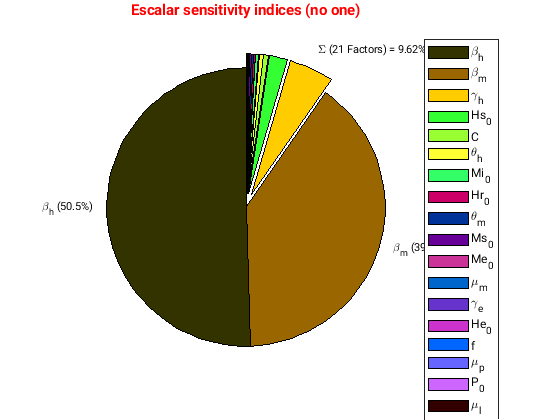

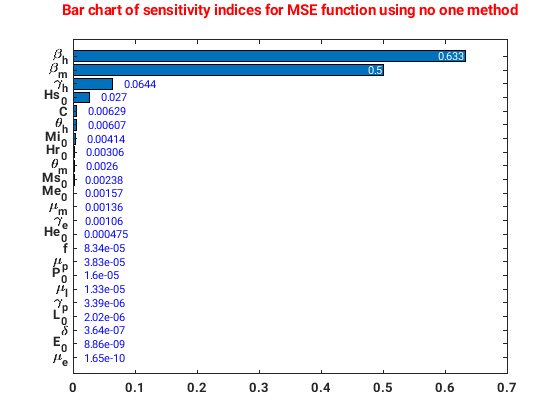

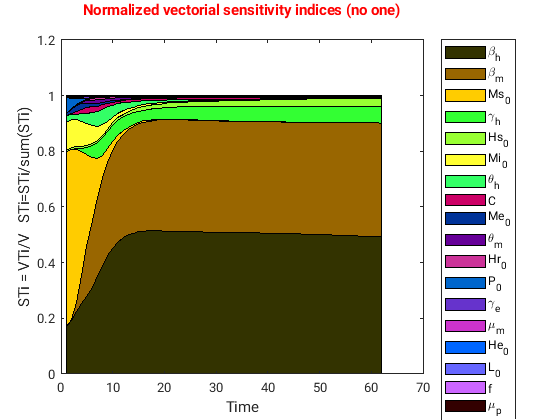

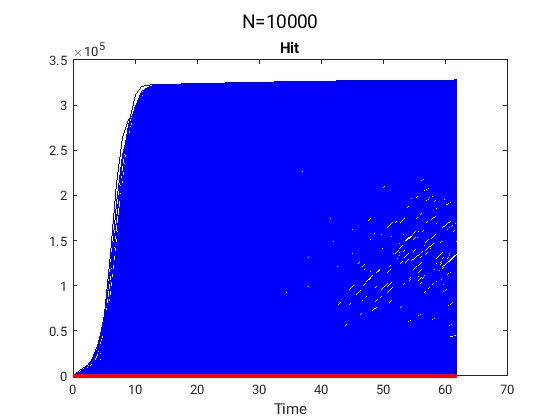

subplot(D1,D2,i)
boxplot([Tma1.Range(i,:);Tma8.Range(i,:);Tma7.Range(i,:)]','Label',{'M(1)','M(2)','M(3)'},'PlotStyle','compact','LabelOrientation','inline')
title(Tma1.Properties.RowNames{i})

end

### 2 models

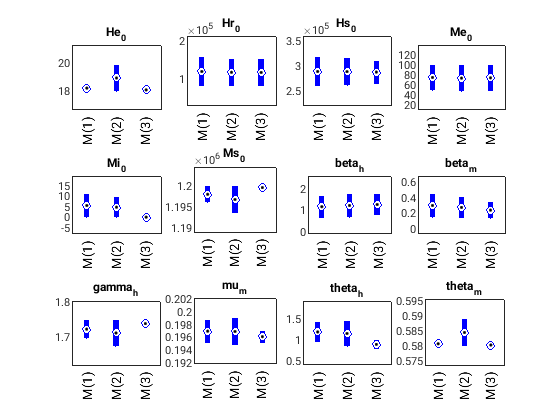

clf
Tma1=T10(minor_set,'Range');
Tma8=T8(minor_set,'Range');
D1 = floor(sqrt(size(Tma1,1))); % Number of rows of subplot
D2 = D1+ceil((size(Tma1,1)-D1^2)/D1);
for i=1:size(Tma1,1)
subplot(D1,D2,i)
boxplot([Tma1.Range(i,:);Tma8.Range(i,:)]','Label',{'10eq','8eq'},'PlotStyle','compact','LabelOrientation','horizontal')
title(Tma1.Properties.RowNames{i})
end

## Improved model 7

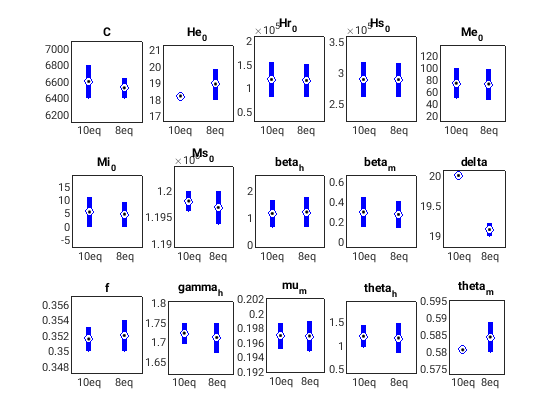

load Results7.mat
T7.Nominal=T7.Estlsqc(:,1);
T=T7;
T.Estlsqc=[];
solver='lsqc';
opt=optimoptions('lsqcurvefit','UseParallel',true,'Display','iter','MaxFunctionEvaluations',4000);
%T.Nominal=nom;
while any(T.Range(:,1)>T.Nominal*0.95) || any(T.Range(:,2)<T.Nominal*1.05)
    T.Range(T.Range(:,1)>T.Nominal*0.95,1)=T.Range(T.Range(:,1)>T.Nominal*0.95,1)*0.8;
    T.Range(T.Range(:,2)<T.Nominal*1.05,2)=T.Range(T.Range(:,2)<T.Nominal*1.05,2)*1.2;

    [T,res]=gsua_pe(T,xdata,ydata2,'solver',solver,'ipoint',T.Nominal','Show','on','opt',opt);
    T.Nominal=T.Estlsqc;
end
save('Improved.mat','T','res')

## Model 7 after fixing Me_0

Sim13 Done
Sim12 Done
Sim11 Done
Sim10 Done
Sim9 Done
Sim8 Done
Sim7 Done
Sim6 Done
Sim5 Done
Sim4 Done
Sim3 Done
Sim2 Done
Sim1 Done
Sim26 Done
Sim39 Done
Sim52 Done
Sim171 Done
Sim170 Done
Sim169 Done
Sim168 Done
Sim167 Done
Sim166 Done
Sim165 Done
Sim164 Done
Sim163 Done
Sim162 Done
Sim161 Done
Sim160 Done
Sim159 Done
Sim158 Done
Sim157 Done
Sim156 Done
Sim155 Done
Sim154 Done
Sim153 Done
Sim152 Done
Sim151 Done
Sim150 Done
Sim149 Done
Sim148 Done
Sim147 Done
Sim146 Done
Sim145 Done
Sim144 Done
Sim143 Done
Sim142 Done
Sim141 Done
Sim140 Done
Sim139 Done
Sim138 Done
Sim137 Done
Sim136 Done
Sim135 Done
Sim134 Done
Sim133 Done
Sim25 Done
Sim24 Done
Sim23 Done
Sim22 Done
Sim21 Done
Sim20 Done
Sim19 Done
Sim18 Done
Sim17 Done
Sim16 Done
Sim15 Done
Sim14 Done
Sim38 Done
Sim37 Done
Sim36 Done
Sim35 Done
Sim34 Done
Sim33 Done
Sim32 Done
Sim31 Done
Sim30 Done
Sim29 Done
Sim28 Done
Sim27 Done
Sim409 Done
Sim408 Done
Sim407 Done
Sim406 Done
Sim405 Done
Sim404 Done
Sim403 Done
Sim402 Done
Sim40

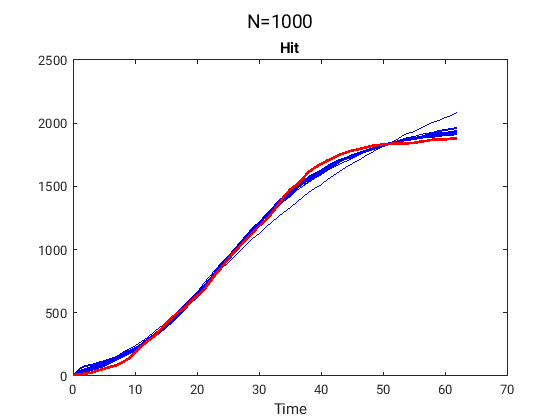

load Results7_fix.mat
y7_2=gsua_eval(T7.Estlsqc,T7,xdata,ydata2);

T7.Nominal=T7.Estlsqc(:,1);
th=sum(res<res(1)*1.01)

th = 257

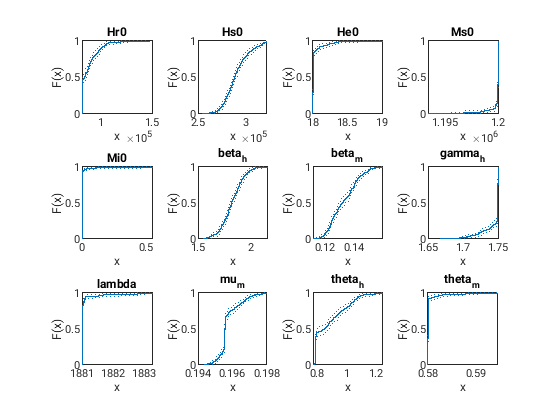

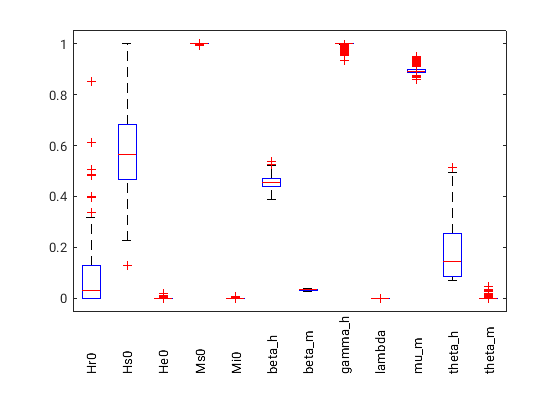

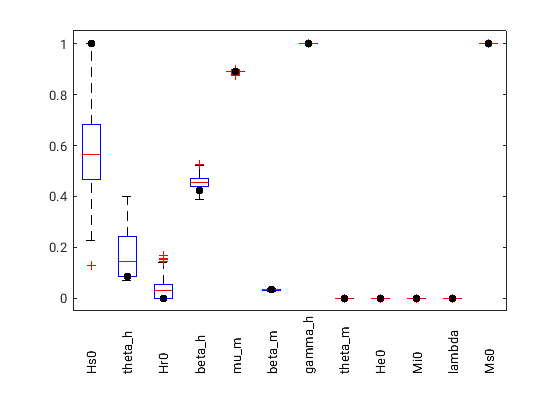

T7_2=gsua_ia(T7,T7.Estlsqc(:,1:th));